## Varying Mass Position

We are acquiring data based on different clip positions.

The first data (full_bottom) refers to the clip attached to the end of the rod. We then proceded from that position, moving the mass every 5 cm. 

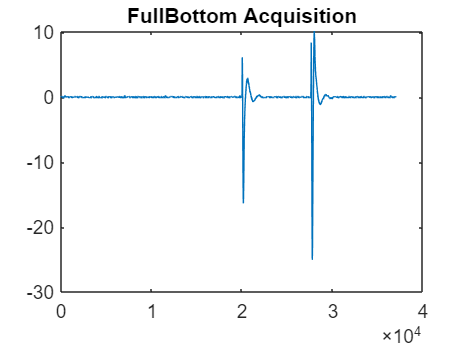

clear
load ("VaryingMassDATA.mat");
plot(data1_fullbottom)
title("FullBottom Acquisition")

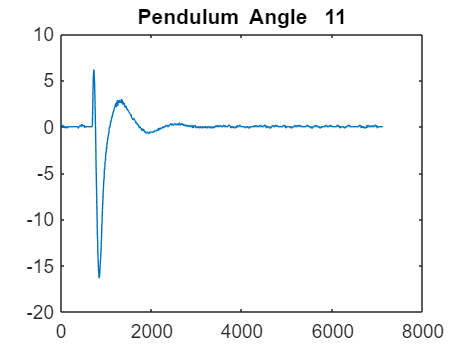

%splitting the 2 impulse responses
Resp11 = data1_fullbottom(1,start_11(1,1).Position:end_11(1,1).Position);
plot(Resp11)
title("Pendulum Angle _ 11")

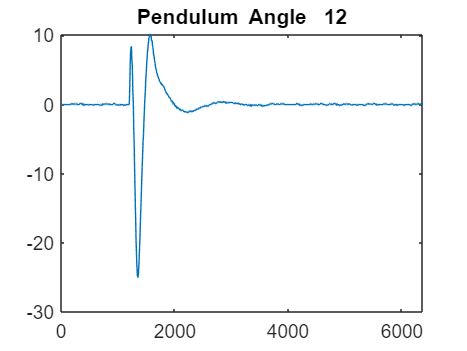

input11=[zeros(1,692),ones(1,5),zeros(1,length(Resp11)-697)];

Resp12 = data1_fullbottom(1,start_12(1,1).Position:end_12(1,1).Position);
plot(Resp12)
title("Pendulum Angle _ 12")

input12=[zeros(1,1202),ones(1,5),zeros(1,length(Resp12)-1207)];
%non linear behaviour can be seen with the 2nd peak higher than the 1st

Resp1=[Resp11,Resp12];
input1=[input11,input12];


abbiamo notato che a causa di un impulso eccessivamente forte, il pendolo inverso mostrava un comportamento apparentemente non lineare.

A riprova di ciò abbiamo visualizzato gli impulsi in questione prima

singolarmente(tf11&tf12) e poi, come verifica, insieme(tf1) (nonlinearityproof). Confrontandoli poi con

altri due impulsi che però non andavano fuori dalla zona di linearità del

pendolo inverso (data2, tf21&tf22 uniti poi in tf2). Difatti con quest'ultimi il modello risultava

tale da garantire dei poli non spostati (tra le dinamiche dei due picchi) (mappa poli zeri di tf11 e tf12 rispetto a tf21 e tf22)

e una corretta approssimazione anche quando fornivamo un singolo ingresso, formato dall'unione dei due impulsi singoli.

disp("now we'll work with the second position of the mass")

now we'll work with the second position of the mass


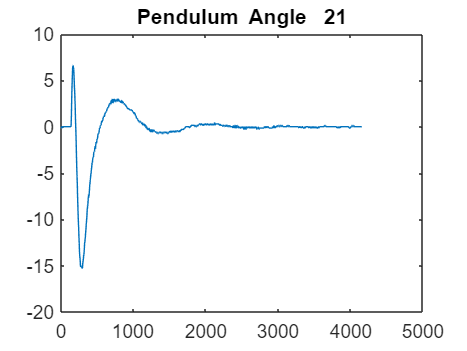

%plot(data2)

Resp21=data2(1,start_21.DataIndex:end_21(1,1).DataIndex);
plot(Resp21)
title("Pendulum Angle _ 21")

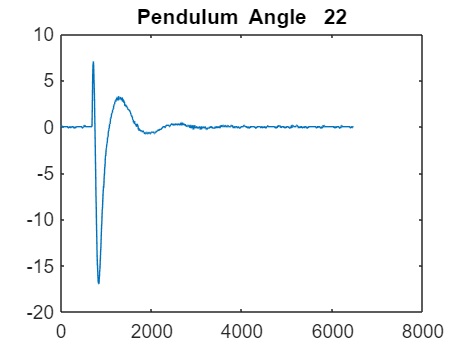

input21=[zeros(1,138),ones(1,5),zeros(1,length(Resp21)-143)];

Resp22=data2(1,start_22.DataIndex:end_22(1,1).DataIndex);
plot(Resp22)
title("Pendulum Angle _ 22")

input22=[zeros(1,684),ones(1,5),zeros(1,length(Resp22)-689)];

Resp2=[Resp21,Resp22];
input2=[input21,input22];

Import Linear response position 1

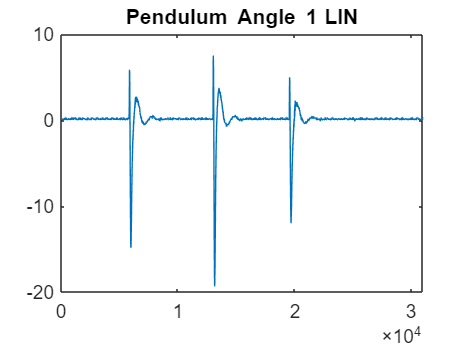

%correction of the first position by acquiring new data staying inside the
%linearity action space.
%Whole data1
data1_fullbottom_Lin = pendulum_angle;
plot(data1_fullbottom_Lin)
title("Pendulum Angle 1_ LIN")

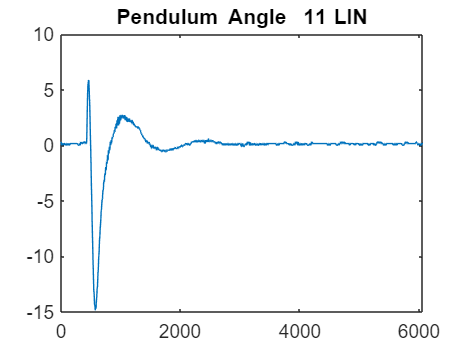



Resp11_LIN = data1_fullbottom_Lin(1,start_11_LIN.DataIndex:end_11_LIN.DataIndex);
plot(Resp11_LIN)
title("Pendulum Angle _ 11_ LIN")

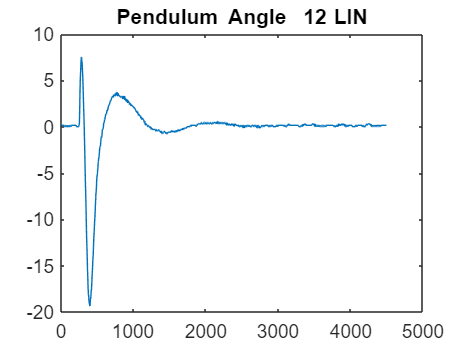


input11_LIN = [zeros(1,428),ones(1,5),zeros(1,length(Resp11_LIN)-433)];


Resp12_LIN = data1_fullbottom_Lin(1,start_12_LIN.DataIndex:end_12_LIN.DataIndex);
plot(Resp12_LIN)
title("Pendulum Angle _ 12_ LIN")


input12_LIN = [zeros(1,245),ones(1,5),zeros(1,length(Resp12_LIN)-250)];
%plot(input12_LIN)
input1_LIN=[input11_LIN input12_LIN];
Resp1_LIN=[Resp11_LIN Resp12_LIN];

stiamo optando per utilizzare un singolo input contenente i 2 impulsi, questo (a causa del nostro essere umani e non robot) fa si che i due impulsi siano leggermente diversi in ampiezza e per tanto la percentuale di fedeltà non risulta massimizzata come invece risulta quando i due impulsi vengono separati in due input diversi (come nel caso dove abbiamo mostrato la non linearità)

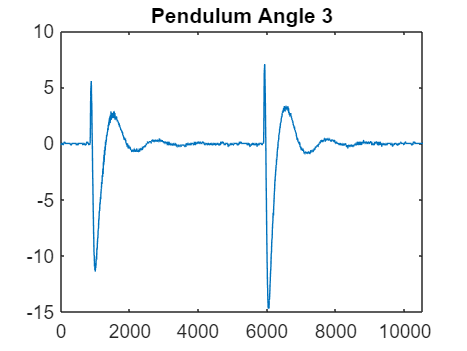

%plot(data3)
Resp3 = data3(8366: 18900);
plot(Resp3)
title("Pendulum Angle 3")

input3=[zeros(1,848),ones(1,5),zeros(1, 5043),ones(1,5),zeros(1,length(Resp3)-(5043+10+848))];
%plot(input3);

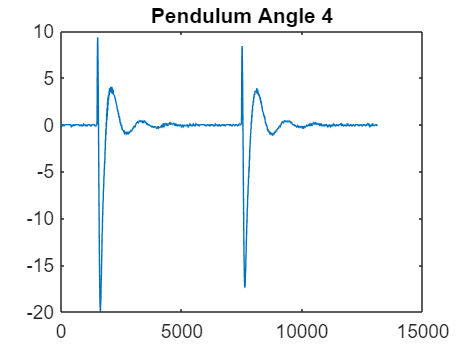

%plot(data4)
Resp4 = data4(4351: 17447);
plot(Resp4)
title("Pendulum Angle 4")

input4=[zeros(1,1491),ones(1,5),zeros(1, 5978),ones(1,5),zeros(1,length(Resp4)-(5978+10+1491))];
%plot(input4);

Al variare della massa, poli e zeri del modello ricostruito si spostano. In particolare, si nota che spostando la clip verso l'encoder, i poli si spostano verso sinistra. 

Questo significa che il sistema risponde in maniera più veloce (avviciniamo la massa al punto in cui diamo l'input)

e cambiano anche la parte immaginaria le sinusoidi sono a frequenza più alta.